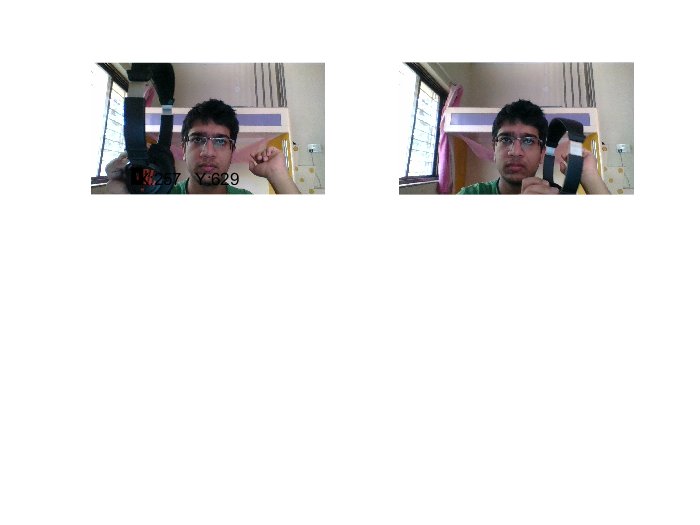

Index exceeds the number of array elements (0).

clear all;
close all;
clc;

vid=videoinput('winvideo',1,'MJPG_1280x720');
set(vid,'ReturnedColorSpace','rgb');
vid.FrameGrabInterval=1;
centmvmtX=[];
centmvmtY=[];

for k=1:3
a=getsnapshot(vid);
grayscale=rgb2gray(a);

r=a(:,:,1);
g=a(:,:,2);
b=a(:,:,3);

c=r-grayscale;
c=im2bw(c,0.2);
c=medfilt2(c,[10 10]);
% imshow(c);
stat=regionprops(c,'BoundingBox','Centroid');
subplot(2,2,k)
imshow(a);
hold on;

pos=stat(1).BoundingBox;
rectangle('Position',pos,'LineWidth',3);
cent=round(stat(1).Centroid);
text(cent(1),cent(2),strcat("X:",num2str(cent(1)),"   Y:",num2str(cent(2))));

centmvmtX=[centmvmtX cent(1)];
centmvmtY=[centmvmtY cent(2)];

% hold off;
end


plot(centmvmtX,centmvmtY,'r','LineWidth',2);


